# MIT 2.12 Introduction to Robotics

## Virtual Lab 11 - Robot Manipulation and Trajectory Planning with Matlab

## Task 2. Plan and Execute Collision-Free Trajectories

## April 2020

## 0. Initial Setup

In this example, we will use the KINOVA Gen3 Manipulator again. We will plan closed-loop collision-free robot trajectories from an initial to a desired end-effector pose using nonlinear model predictive control. 

clear all
close all

% Again, we first load the robot
robot = loadrobot('kinovaGen3', 'DataFormat', 'column');

% Extract information from the RBT model
numJoints = numel(homeConfiguration(robot));
endEffector = "EndEffector_Link"; 

Next: we set up the tast specification. Including the initial and final pose of the robot.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

**TO DO**: Please fill out the following line


 currentRobotJConfig = ik(); %% Modify here
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');

**Question**: What is the following line specifying? Why these two entries?

poseFinal = [taskFinal(1:3,4);anglesFinal']; 

**Question****:** Is this task-space control or joint-space control? How do you learn that from the code?

## 1.a Import Obstacles and Check Collisions

The implementation is done for you. But please take a look at the helper function.

collisionHelper = helperManipCollsionsKINOVA(robot);
collisionHelper.ExhaustiveChecking = true;

You can specify whether the collision is moving or not. You can also add static collision objects in `helperCreateObstaclesKINOVA.`

isMovingObst = true;
helperCreateObstaclesKINOVA;

Visualize the result

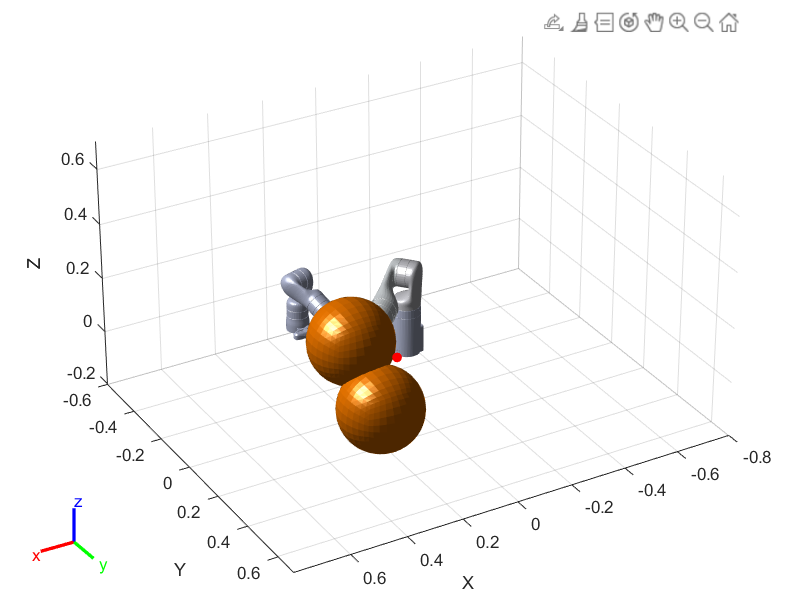

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

**TO DO**: Go into helperCreateObstaclesKINOVA and add a sphere in the obstracle and save the figure.

## 1.b Nonlinear Model Predictive Controller

safetyDistance = 0.01;  %Please specify your own safety distance. Note that it might not converge if you set too big of a distance.

% The controller is set up here. If you have interest in the implementation or MPC itself please take a close look at the code. 
% Note that this part requires the installation of Model Predictive Control Toolbox.
helperDesignNLMPCobjKINOVA;   

## 1.c Trajectory Planning

First, we initialize the simulation time and data.

% Set up simulation time step.
maxIters = 50;
u0 = zeros(1,numJoints);
mv = u0;
time = 0;
goalReached = false;

% Set initial condition
positions = zeros(numJoints,maxIters);
positions(:,1) = x0(1:numJoints)';

velocities = zeros(numJoints,maxIters);
velocities(:,1) = x0(numJoints+1:end)';

accelerations = zeros(numJoints,maxIters);
accelerations(:,1) = u0';

timestamp = zeros(1,maxIters);
timestamp(:,1) = time;

The following commands generates the collision-free trajectory with the NLMPC toolbox. It uses the [`nlmpcmove`](https://www.mathworks.com/help/mpc/ref/nlmpc.nlmpcmove.html) function for closed-loop trajectory generation. Specify the trajectory generation options using an [`nlmpcmoveopt`](https://www.mathworks.com/help/mpc/ref/nlmpcmoveopt.html) object. Each iteration calculates the position, velocity, and acceleration of the joints to avoid obstacles as they move towards the goal. The `helperCheckGoalReachedKINOVA` script checks if the robot has reached the goal. The `helperUpdateMovingObstacles` script moves the obstacle locations based on the time step.

options = nlmpcmoveopt;
for timestep=1:maxIters
    disp(['Calculating control at timestep ', num2str(timestep)]);
    % Optimize next trajectory point 
    [mv,options,info] = nlmpcmove(nlobj,x0,mv,[],[], options);
    if info.ExitFlag < 0
        disp('Failed to compute a feasible trajectory. Aborting...')
        break;
    end
    % Update states and time for next iteration
    x0 = info.Xopt(2,:);
    time = time + nlobj.Ts;
    % Store trajectory points
    positions(:,timestep+1) = x0(1:numJoints)';
    velocities(:,timestep+1) = x0(numJoints+1:end)';
    accelerations(:,timestep+1) = info.MVopt(2,:)';
    timestamp(timestep+1) = time;
    % Check if goal is achieved 
    helperCheckGoalReachedKINOVA;
    if goalReached
        break;
    end
    % Update obstacle pose if it is moving
    if isMovingObst
        helperUpdateMovingObstaclesKINOVA;
    end
end

Calculating control at timestep 1


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Calculating control at timestep 2


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Calculating control at timestep 3


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Calculating control at timestep 4


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Calculating control at timestep 5


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Calculating control at timestep 6


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Calculating control at timestep 7


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Calculating control at timestep 8


Slack variable unused or zero-weighted in your custom cost function. All constraints will be hard.


Target configuration reached.


## 1.c Visualize the result

% Trim to given time step
tFinal = timestep+1;
positions = positions(:,1:tFinal);
velocities = velocities(:,1:tFinal);
accelerations = accelerations(:,1:tFinal);
timestamp = timestamp(:,1:tFinal);

visTimeStep = 0.2;

Similar to the previous task, we use the joint space model to execute the planned trajectory.

motionModel = jointSpaceMotionModel('RigidBodyTree', robot);

% Control robot to target trajectory points in simulation using low-fidelity model
initState = [positions(:,1);velocities(:,1)];
targetStates = [positions;velocities;accelerations]';    
[t,robotStates] = ode15s(@(t,state) helperTimeBasedStateInputsKINOVA(motionModel, timestamp, targetStates, t, state), [timestamp(1):visTimeStep:timestamp(end)], initState);

Finally, visualize the motion

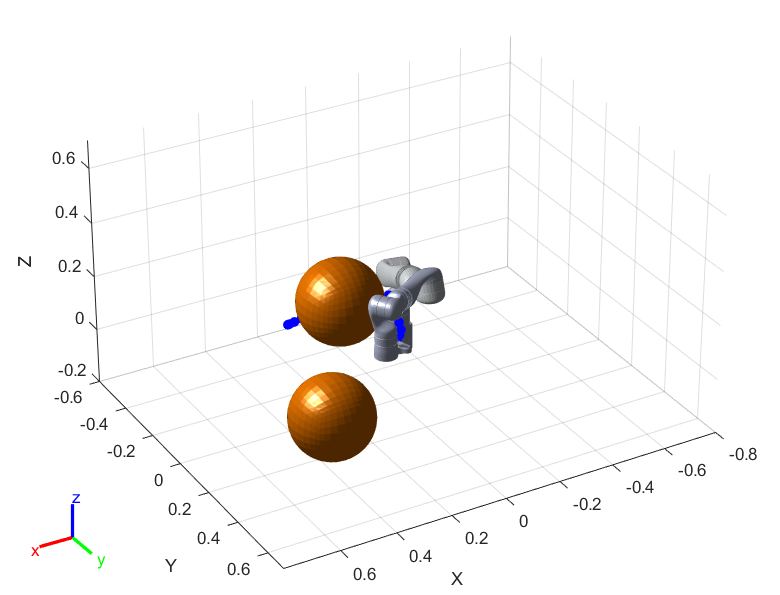

helperFinalVisualizerKINOVA;

**TO DO**: Repeat the above for your own obstacle position and target final state of the manipulator. Plot and save the result.

## For the original guideline, please checkout:

[https://www.mathworks.com/help/robotics/examples/plan-and-execute-collision-free-trajectory-kinova-gen3.html](https://www.mathworks.com/help/robotics/examples/plan-and-execute-collision-free-trajectory-kinova-gen3.html)